# PTT 爬蟲練習

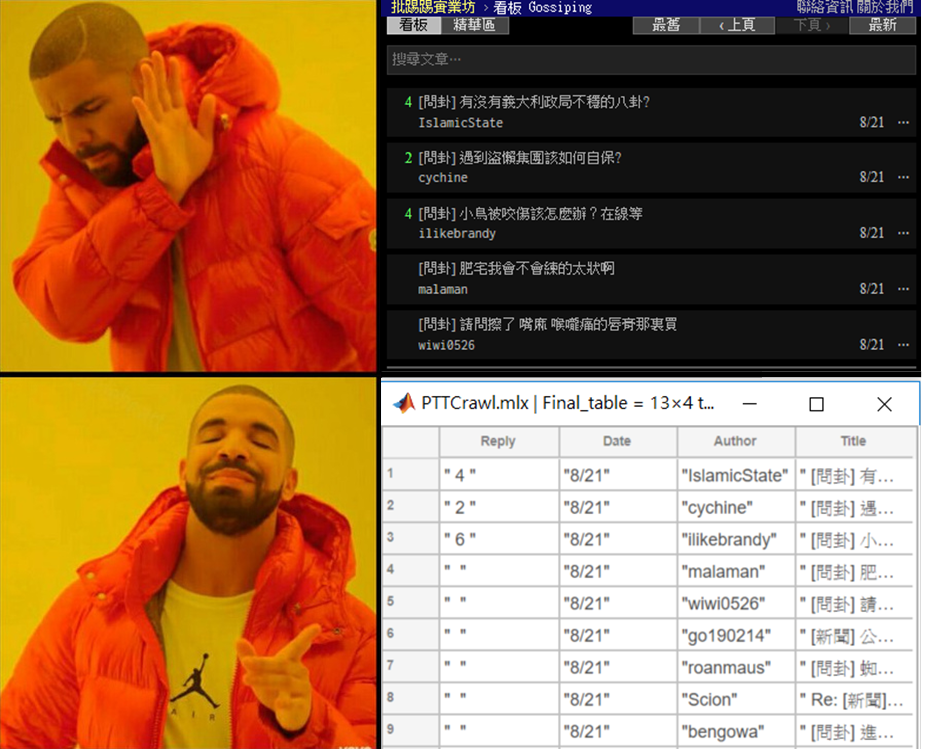

此練習程式碼用於爬取PTT版上文章資訊，文本分析工具箱的需求單純用來移除html tag

若是使用這不具備文本分析工具箱，可用一般文字處理手法移除

 ============================ 

#### 工具箱需求 Toolbox Requirement: 

- [文本分析工具箱 Text Analytics Toolbox] 

============================ 

#### 參數說明 : 

## 使用說明:

#### 無任何輸入

without_input = PTTCrawler

elapsedTime = 0.3550

without_input = 15×4 table
    Reply        Date           Author                      Title                 
    _____    _____________    __________    ______________________________________

       9     2022年06月23日    ss8901234     "[問卦]大谷翔平二刀流有多難"              
       5     2022年06月23日    usnavyseal    "[爆卦]1分鐘看完美國01/2020-06/2022的通膨"
       1     2022年06月23日    lelingzi      "[問卦]叫8+9猴子是不是在侮辱猴子？"        
       6     2022年06月23日    msis20        "[問卦]有沒有年利率216%股票的八卦？"       
       7     2022年06月23日    P00832129     "[問卦]妳離去，那天忽然頃盆大雨"           
       5     2022年06月23日    Beanoodle     "[問卦]漲電價冷氣還敢開16度？？"           
       7     2022年06月23日    -             "(本文已被刪除)[fge16]"                 
     NaN     2022年06月23日    -             "(本文已被刪除)[Axwell]"                
      11     2022年06月23日    wbsinger      "[新聞]快訊／桃園自來水管爆裂！路面炸出2m長" 
       4   

####  輸入查詢版

with_site = PTTCrawler('Tech_Job')

elapsedTime = 0.2910

with_site = 21×4 table
    Reply        Date           Author                         Title                  
    _____    _____________    ___________    _________________________________________

     NaN     2022年06月23日    brbear         "Fw:[新聞]炸竹科等於打垮美國？澳洲記者2001神預" 
       5     2022年06月23日    FrankyWu       "[討論]請益東京威力設備工程師薪資"            
       7     2022年06月23日    ireneyang      "[請益]日本熊本台積電面試"                   
     NaN     2022年06月23日    wahaha23       "[新聞]缺料…晶圓代工擴產放緩"                
     NaN     2022年06月23日    -              "(本文已被刪除)<sheepmanager>"       
     NaN     2022年06月23日    -              "(已被mmkntust刪除)<bb0x0>版規一.七"  
      32     2022年06月23日    duck21632      "[請益]Offer請益"                         
       3     2022年06月23日    mmkntust       "[公告]bb0x0違反版規一.七退文.水桶一個月"     
     NaN     2022年06月23日    -              "

with_site = PTTCrawler("Tech_Job")

elapsedTime = 0.2482

with_site = 21×4 table
    Reply        Date           Author                         Title                  
    _____    _____________    ___________    _________________________________________

     NaN     2022年06月23日    brbear         "Fw:[新聞]炸竹科等於打垮美國？澳洲記者2001神預" 
       5     2022年06月23日    FrankyWu       "[討論]請益東京威力設備工程師薪資"            
       7     2022年06月23日    ireneyang      "[請益]日本熊本台積電面試"                   
     NaN     2022年06月23日    wahaha23       "[新聞]缺料…晶圓代工擴產放緩"                
     NaN     2022年06月23日    -              "(本文已被刪除)<sheepmanager>"       
     NaN     2022年06月23日    -              "(已被mmkntust刪除)<bb0x0>版規一.七"  
      32     2022年06月23日    duck21632      "[請益]Offer請益"                         
       3     2022年06月23日    mmkntust       "[公告]bb0x0違反版規一.七退文.水桶一個月"     
     NaN     2022年06月23日    -              "

####  輸入查詢版與是否輸出檔案

with_siteNflag = PTTCrawler('Tech_Job',true)

elapsedTime = 0.3708

with_siteNflag = 21×4 table
    Reply        Date           Author                         Title                  
    _____    _____________    ___________    _________________________________________

     NaN     2022年06月23日    brbear         "Fw:[新聞]炸竹科等於打垮美國？澳洲記者2001神預" 
       5     2022年06月23日    FrankyWu       "[討論]請益東京威力設備工程師薪資"            
       7     2022年06月23日    ireneyang      "[請益]日本熊本台積電面試"                   
     NaN     2022年06月23日    wahaha23       "[新聞]缺料…晶圓代工擴產放緩"                
     NaN     2022年06月23日    -              "(本文已被刪除)<sheepmanager>"       
     NaN     2022年06月23日    -              "(已被mmkntust刪除)<bb0x0>版規一.七"  
      32     2022年06月23日    duck21632      "[請益]Offer請益"                         
       3     2022年06月23日    mmkntust       "[公告]bb0x0違反版規一.七退文.水桶一個月"     
     NaN     2022年06月23日    -          

## **主函式**

function Data = PTTCrawler(site,genFile)
tic; % 使用 tic-toc 計算程式運行爬取時間
narginchk(0,3) % 檢查使用者輸入的變數數量是否符合
switch nargin
    case 0
        % 使用者沒有任何輸入，預設查詢八卦版
        site  = 'Gossiping';
        genFile = false;
        Data = StartCrawl(site,genFile);
    case 1
        % 使用者輸入欲查詢的板
        if isa(site,'string')
            site = char(site);
        end
        genFile = false;
        chkClass(site,genFile)
        Data = StartCrawl(site,genFile);
    case 2
        % 使用者輸入欲查詢的板並決定是否輸出檔案
        if isa(site,'string')
            site = char(site);
        end
        chkClass(site,genFile);
        Data = StartCrawl(site,genFile);
end

elapsedTime = toc
end

## Nested Function 架構

PTT 頁面爬取主程式

function Data = StartCrawl(site,genFile)

opt = weboptions('KeyName','cookie','KeyValue','over18=1'); %八卦版需要年齡驗證
url = ['https://www.ptt.cc/bbs/',site,'/index.html'];

% 使用 try-catch 來抓去網路連線可能發生的錯誤，並提供使用者錯誤訊息
try
    Ptt_raw = webread(url,opt);
catch status
    if strcmp(status.identifier,'MATLAB:webservices:UnknownHost')
        error('請檢查網路連線')
    elseif strcmp(status.identifier,'MATLAB:webservices:Timeout')
        error('連線時間過長')
    else
        error('未知錯誤')
    end
end

Data = cleanData;    % Output

if genFile
    filename = ['PTT爬取結果_',site,'.csv'];
    writetable(Data,filename)
end

% 將非結構性的爬蟲資料整理成 table 格式
    function Data = cleanData
        % 從 html 檔純文字中擷取資訊
        Title = regexp(Ptt_raw,'<?div class="title">.*?</div>?','match')';    % 文章標題
        Date = regexp(Ptt_raw,'<?div class="date">.*?</div>?','match')';    % 發表日期
        Author = regexp(Ptt_raw,'<?div class="author">.*?</div>?','match')';    % 發文者帳號
        Reply = regexp(Ptt_raw,'<?div class="nrec">.*?</div>?','match')';    % 回覆數量
        structTable = [Reply,Date,Author,Title];
        
        % 移除 HTML Tags
        % ===== Text Analytics Toolbox Required ======
        cleanData = string(cellfun(@eraseTags,structTable,'UniformOutput',0)); % eraseTags: 刪除網頁標籤
        % ============================================
        
        % If Text Analytics Toolbox Not Installed, Use This Line instead 
        % ============================================
        %         cleanData = string(cellfun(@(x)regexprep(x,'(<.*?>)',''),structTable,'UniformOutput',0));
        % ============================================
        cleanData = regexprep(cleanData,'(\n|\t|\r| )','');
        
        Data = array2table(cleanData,'VariableNames',{'Reply','Date','Author','Title'});
        Data.Reply = str2double(Data.Reply);
        Data.Date = datetime(Data.Date,'InputFormat','MM/dd','Format','yyyy年MM月dd日');
        Data.Author = categorical(Data.Author);
    end
end

## SubFunction 架構

檢查使用者輸入的變數型態是否正確

function chkClass(title,genFile)
chktitle = isa(title,'char');
chkgenFile = isa(genFile,'logical');
if ~chktitle|~chkgenFile
    error('輸入格式錯誤')
end
end